# **Wireless Communications**

**Computer Assignment 1 - Soroush Mesforush Mashhad - 810198472**

#### ***Question 1***

Part a)

N = 1e5;%Number of users
d_0 = 10;%Minimum Distance of user to BS
D = 1000;%Maximum Distance of user to BS
n = 4;%Path loss exponent
N_0dBm = -175;
BW = 1e6;%Bandwidth

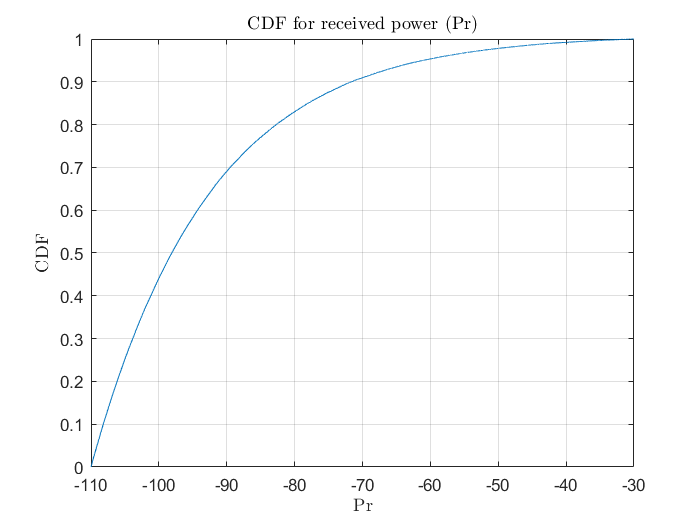

DistVec = (D-d_0).*rand(N,1,'double') +d_0;
P0 = 10.*log10(1e-6);
P0_dBm = P0+30;
Pr_dBm = P0_dBm - 10*n.*log10(sort(DistVec)/d_0);
cdfplot(Pr_dBm)
xlabel('Pr','Interpreter','latex')
ylabel('CDF','Interpreter','latex')
title('CDF for received power (Pr)','Interpreter','latex')

Part b)

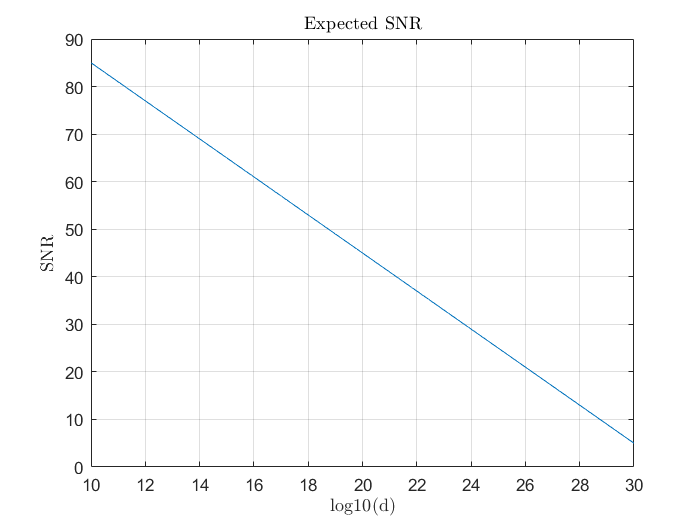

N0_dB = N_0dBm - 30;
N0 = 10^(N0_dB/10);
Pnoise = N0*BW;
Pnoise_dBm = 10*log10(Pnoise) + 30;
SNR = Pr_dBm-Pnoise_dBm;
dplot =10.*log10(sort(DistVec));
plot(dplot,SNR)
grid on
xlabel('log10(d)','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('Expected SNR','Interpreter','latex')

From here on we shall consider the shadowing effect.

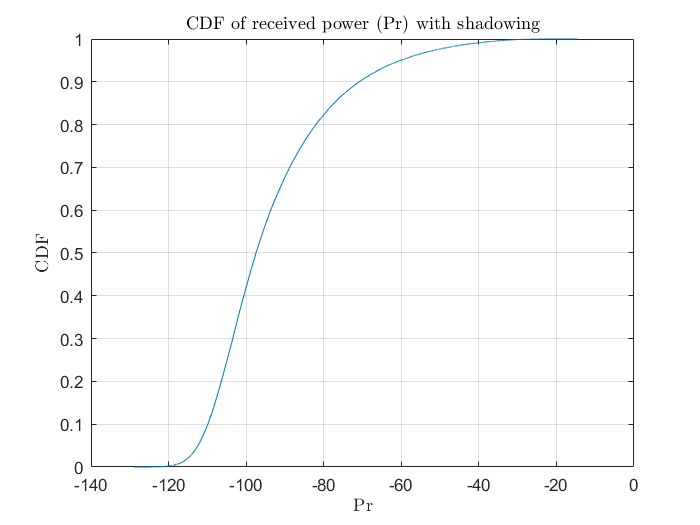

sigma_dB = 5;
mu = 0;
X_dB = normrnd(mu,sigma_dB,[N,1]);
Pr_dBmShdw = P0_dBm - 10*n.*log10(sort(DistVec)/d_0)+X_dB;
cdfplot(Pr_dBmShdw)
xlabel('Pr','Interpreter','latex')
ylabel('CDF','Interpreter','latex')
title('CDF of received power (Pr) with shadowing','Interpreter','latex')

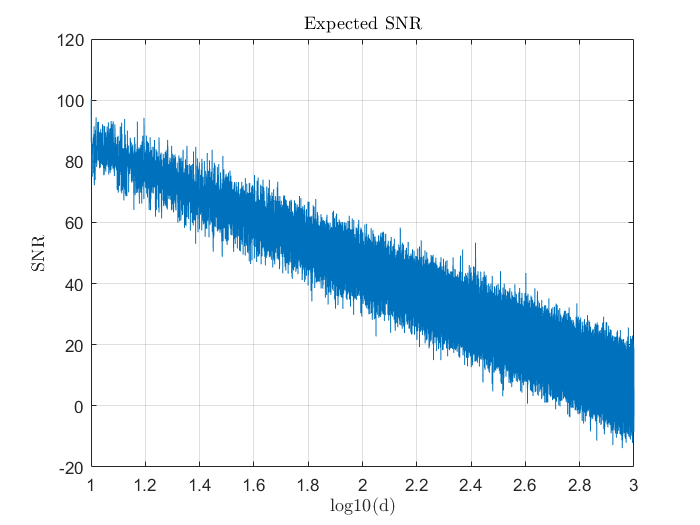

SNR_Shdw = Pr_dBmShdw-Pnoise_dBm;
dplot = log10(sort(DistVec));
plot(dplot,SNR_Shdw)
grid on
xlabel('log10(d)','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('Expected SNR','Interpreter','latex')

Part d)

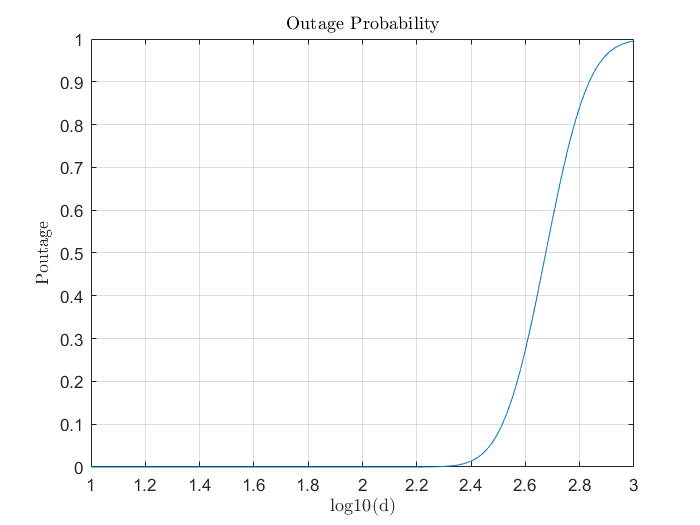

%Here we shall plot the outage probability plot.
SNRMin_dB = 18;
%To find where SNR_Shdw>SNRMin_dB we use do the following stuff.
P_outage = 1- qfunc((SNRMin_dB-(SNR))/sigma_dB);
plot(log10(sort(DistVec)),P_outage);
xlabel("log10(d)",'Interpreter','latex');
ylabel("Poutage",'Interpreter','latex');
title('Outage Probability','Interpreter','latex')
grid on;

Part h)

%The theoretical calculation is as follows.
PrD = P0_dBm - 10*n.*log10(D/d_0);
a = ((Pnoise_dBm + SNRMin_dB)-PrD)/(sigma_dB);
b = (10*n.*log10(exp(1)))/(sigma_dB);
Ctheoretical = qfunc(a) + exp((2-2*a*b)/(b.^2)).*qfunc((2-a.*b)/(b));
disp('The theoretical values are :')

The theoretical values are :


disp(Ctheoretical)

    0.2632



S = Ctheoretical*pi*D^2;
disp(S)

   8.2688e+05



%The simulation is as follows.
sortedSNR = sort(SNR,'descend');
ind=0;
for i=1:N
    if(sortedSNR(i)<SNRMin_dB)
     ind=i;
     break
    end
end
DistVecSort = sort(DistVec);
d_max = DistVecSort(ind);
Stot = pi*d_max^2;
CSim = Stot/(pi*D^2);
disp('The simulation results are :')

The simulation results are :


disp(CSim)

    0.2239



disp(Stot)

   7.0332e+05



#### ***Question 2***

Part a)

%Here we shall define the parameters.
Clusters = 15;
a = 1;
b=10;
Tau = a + (b-a).*rand(Clusters,1);
Phi = rand(Clusters,1)*pi*0.5;
rI =randn(Clusters,1).*sqrt(0.5).*sqrt(Tau.^(-4)*10.^(-3));
rQ = randn(Clusters,1).*sqrt(0.5).*sqrt(Tau.^(-4)*10.^(-3));
r = sqrt(rI.^2+rQ.^2);

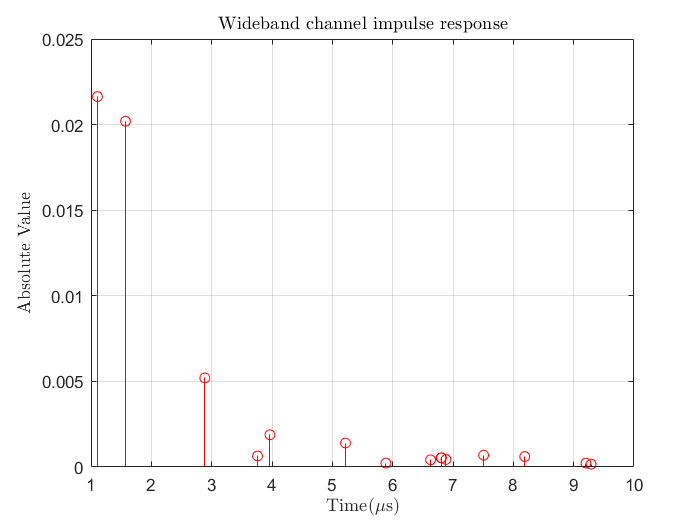

c = r.*exp(1i*Phi);
stem(Tau,abs(c),'r','-o');
xlabel("Time($\mu$s)",'Interpreter','latex');
ylabel("Absolute Value",'Interpreter','latex');
title('Wideband channel impulse response','Interpreter','latex')
grid on;

freq=linspace(0,1e6:1e6);
CF = zeros(1,length(freq));
ind=1;
while ind<Clusters
   CF = CF + r(ind).*exp(-1i*Phi(ind)).*exp(1i*2*pi.*freq.*Tau(ind)*1e-6);
   ind=ind+1;
end

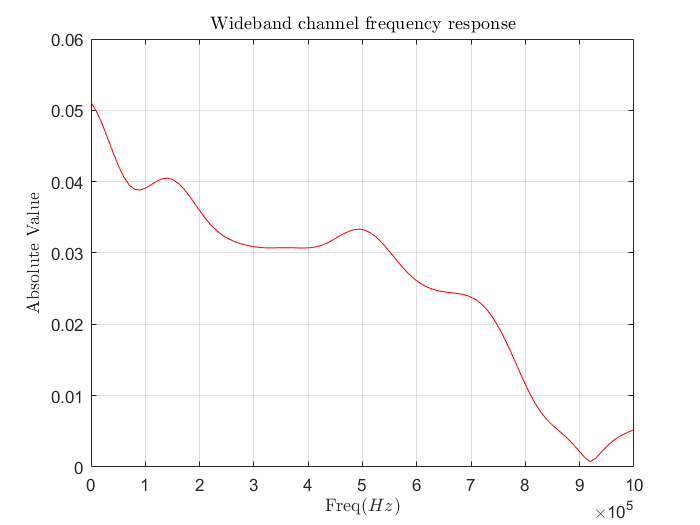

plot(freq,abs(CF),'r');
xlabel("Freq($Hz$)",'Interpreter','latex');
ylabel("Absolute Value",'Interpreter','latex');
title('Wideband channel frequency response','Interpreter','latex')
grid on;

Part b)

Sim = 1e5;
fc=3e9;
Velocity = 3e1;
c = 3e8;
Wavelength=c/fc;
ind = 1;
PowVec=zeros(1,Sim);

while ind<Sim
    a = 1;
    b=10;
    Tau = a + (b-a).*rand(Clusters,1);
    Phi = rand(Clusters,1)*pi*0.5;
    rI =randn(Clusters,1).*sqrt(0.5).*sqrt(Tau.^(-4)*10.^(-3));
    rQ = randn(Clusters,1).*sqrt(0.5).*sqrt(Tau.^(-4)*10.^(-3));
    r = sqrt(rI.^2+rQ.^2);
    DopplerPhase = 2*pi*Velocity*cos(Phi)/Wavelength;
    h = r .* exp(1i*(DopplerPhase-2*pi*fc.*Tau*1e-6));
    PowVec(ind) = sum(abs(h).^2);
    ind=ind+1;
end
MeanPow = mean(PowVec)

MeanPow = 5.5627e-04

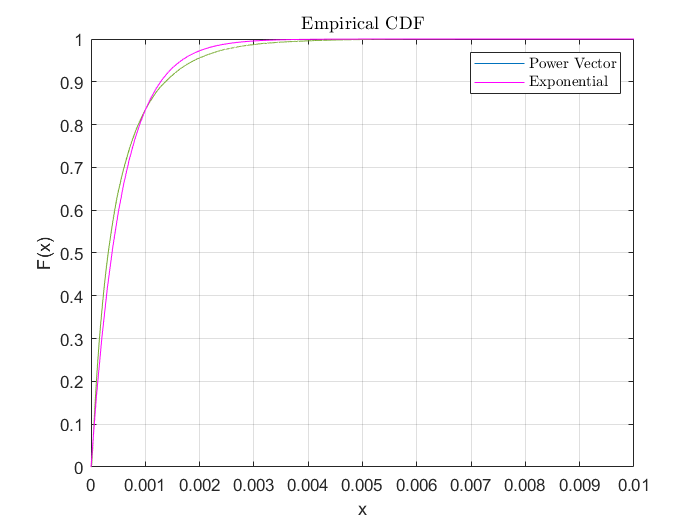

cdfplot(PowVec)
hold on
pd = fitdist(PowVec','Exponential');
x = 0:0.0001:0.01;
p=cdf(pd,x);
plot(x,p,'magenta')
grid on;
legend('Power Vector', 'Exponential','Interpreter','latex');